% select experiment
E_struct = expCell{3};

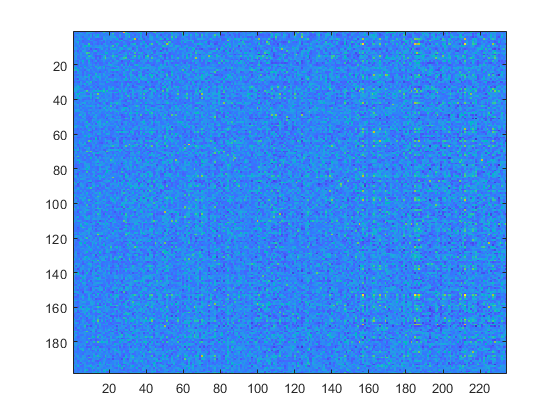

DM1 = zscore(E_struct{1}.DataMatrix);
DM2 = zscore(E_struct{2}.DataMatrix);
corr_mat = zeros(size(DM1,2),size(DM2,2));

mlen = min(size(DM1,1), size(DM2,1));
DM1 = DM1(1:mlen, :);
DM2 = DM2(1:mlen, :);


for i = 1:size(DM1,2)
    for j = 1:size(DM2,2)
        corr_mat(i,j) = corr2(DM1(:,i), DM2(:,j));
    end
end
figure,
imagesc(corr_mat)

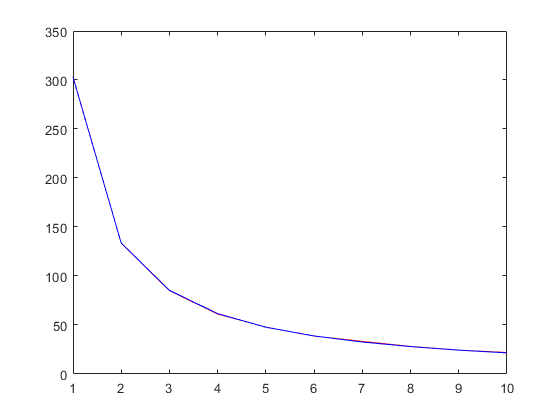

% determine number of clusters
mean_dist_to_c1 = [];
mean_dist_to_c2 = [];
for kn = 1:10
    [idx, centro, sumd] = kmeans(corr_mat, kn);
    mean_dist_to_c1 = [mean_dist_to_c1, mean(sumd)];
    [idx, centro, sumd] = kmeans(corr_mat', kn);
    mean_dist_to_c2 = [mean_dist_to_c2, mean(sumd)];
end

figure,plot(1:10, mean_dist_to_c1,'r');
hold on, plot(1:10, mean_dist_to_c2,'b');

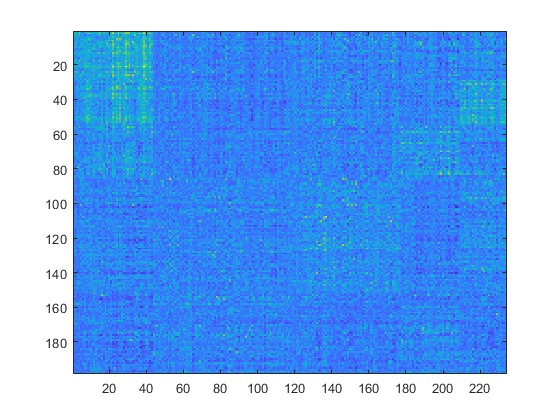

% clustering...

kn=5; % specify number of clusters
rng(42); % set random seed
idx1 = kmeans(corr_mat, kn);
idx2 = kmeans(corr_mat', kn);
[~,c_order1] = sort(idx1);
[~,c_order2] = sort(idx2);
figure, imagesc(corr_mat(c_order1,c_order2));


% visualize clustering results

PlotSelectedCells(E_struct{1}, find(idx1 == 2)); % change idx to cluster you want to visualize
PlotSelectedCells(E_struct{2}, find(idx2 == 1));


SlideCorr(E_struct{1}, E_struct{2}, 1500,60,{find(idx1==3), find(idx2==4)});


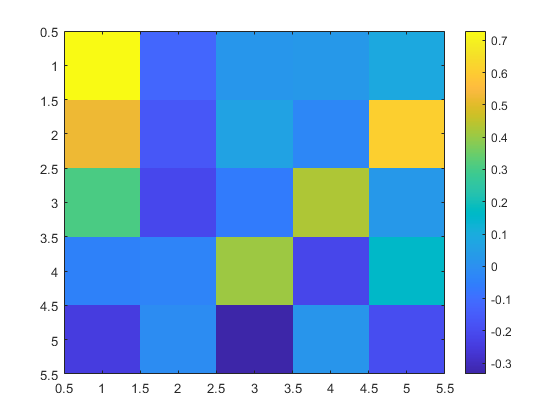

% corr matrix by cluster x cluster
corr_cluster = zeros([kn,kn]);
for i = 1:kn
    for j = 1:kn
        corr_cluster(i,j) = corr2(mean(DM1(:,find(idx1==i)),2), mean(DM2(:,find(idx2==j)),2));
    end
end
figure, imagesc(corr_cluster), colorbar

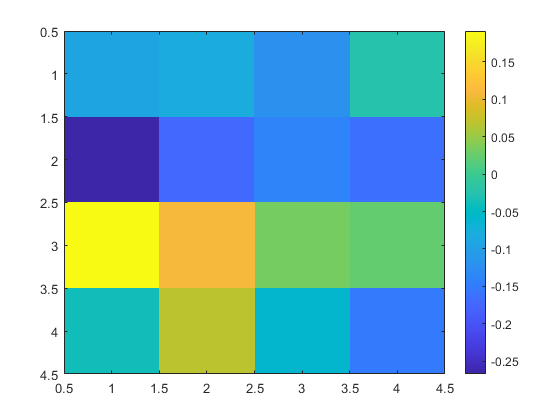

% corr by cluster x cluster removal
corr_cluster_remv = zeros([kn, kn]);
raw_corr = corr2(mean(DM1,2), mean(DM2,2));
for i =1:kn
    for j = 1:kn
        temp = raw_corr-corr2(mean(DM1(:,find(idx1~=i)),2), mean(DM2(:,find(idx2~=j)),2));
        % normalize by number
        temp = temp/(length(find(idx1==i))+length(find(idx2==j))) * (size(DM1,2)+size(DM2,2))/kn;
        corr_cluster_remv(i,j) = -temp;
%         corr_cluster_remv(i,j) = corr2(mean(DM1(:,find(idx1~=i)),2), mean(DM2(:,find(idx2~=j)),2));
    end
end
figure, imagesc(corr_cluster_remv), colorbar

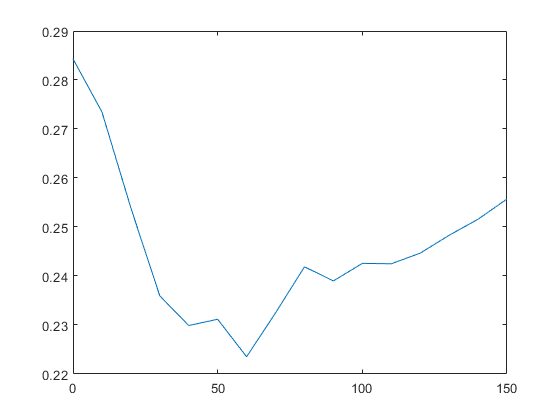

% effect of removing the first n seconds
t_corr = [];
for n = 0:10:150
    t_corr = [t_corr, corr2(mean(DM1(n*30+1:end,:),2), mean(DM2(n*30+1:end,:),2))];
end
figure, plot(0:10:150, t_corr);

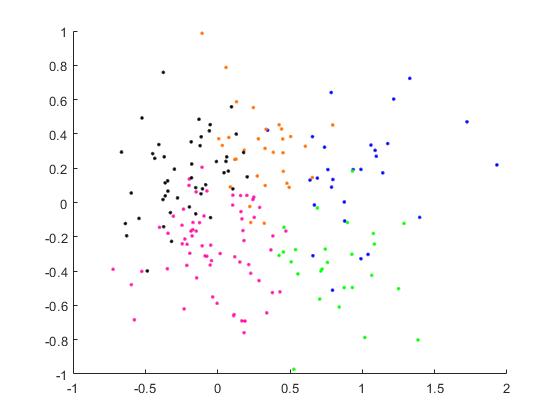

%% PCA plot & behavior etc. 

[coe, score, lat, ~, expled] = pca(corr_mat);
Z = corr_mat * coe(:, 1:3);
cls = maxdistcolor(kn, @sRGB_to_CIELab);
figure, a = axes('NextPlot','add');
for i = 1:kn
    this_clust = find(idx1 == i);
    plot3(a,Z(this_clust, 1),Z(this_clust,2),Z(this_clust,3),'.','Color',cls(i,:));
end

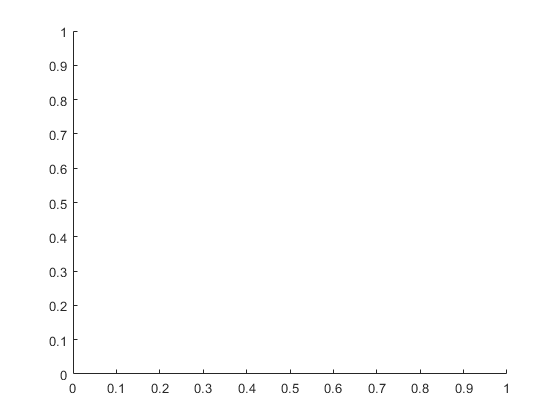


figure, b = axes('NextPlot', 'add');

behav_class = {E_ROC{1, 1}{1, 1}.sigCell.sbj.ps_only,E_ROC{1, 1}{1, 1}.sigCell.sbj.ap_only,E_ROC{1, 1}{1, 1}.sigCell.sbj.mix,E_ROC{1, 1}{1, 1}.sigCell.sbj.other,E_ROC{1, 1}{1, 1}.sigCell.sbj.rt_only};

Undefined variable E_ROC.

% behav_class = {E_ROC{1, 1}{1, 1}.sigCell.sbj_only, E_ROC{1, 1}{1, 1}.sigCell.opp_only,E_ROC{1, 1}{1, 1}.sigCell.sbj_opp_mix,E_ROC{1, 1}{1, 1}.sigCell.other};
cls = maxdistcolor(length(behav_class), @sRGB_to_CIELab);
for i = 1:length(behav_class)
    this_chunk = behav_class{i};
    plot(b, Z(this_chunk,1), Z(this_chunk,2), '.','Color',cls(i,:));
    
end

